## **Read Data**

data = load('/Users/rogermatos/Documents/Deep Learning/InsectClassification/matlab_dataset/insect_dataset.mat');

all_images = data.all_images;
all_dnas = data.all_dnas;
all_labels = data.all_labels;
train_loc = data.train_loc;
val_seen_loc = data.val_seen_loc;
val_unseen_loc = data.val_unseen_loc;
test_seen_loc = data.test_seen_loc;
test_unseen_loc = data.test_unseen_loc;
species2genus = data.species2genus;
described_species_labels_train = data.described_species_labels_train;
described_species_labels_trainval = data.described_species_labels_trainval;
% all_boldids = data.all_boldids;

## **Prepare data**

numClasses = numel(unique(all_labels));

trainData = all_dnas(train_loc, :, :);
trainData = reshape(trainData, [13039 658 5 1]);
trainData = permute(trainData,[2,3,4,1]);
trainLabels = all_labels(train_loc);

valSeenData = all_dnas(val_seen_loc, :, :);
valSeenData = reshape(valSeenData, [ 3234 ,658, 5, 1,]);
valSeenData = permute(valSeenData,[2,3,4,1]);

valSeenLabels = all_labels(val_seen_loc);

numerical_train = trainLabels;
numerical_valSeen = valSeenLabels;

all_categorical_labels = categorical(all_labels)

all_categorical_labels = 1×32424 categorical array
  Columns 1 through 3958

     1      1      1      1      1      1      1      1      1      1      1      2      2      2      2      2      2      2      2      2      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      3      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      4      5      5      5      5      5      5      5      5      5      5      5      5      5      5      5      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      6      7

trainLabels = categorical(trainLabels);
valSeenLabels = categorical(valSeenLabels);
trainLabels = categorical(trainLabels ,categories(all_categorical_labels));
valSeenLabels = categorical(valSeenLabels ,categories(all_categorical_labels));

size(trainData)

ans =          658           5           1       13039


## **Network architecture**

layers = [
    
    inputLayer([658, 5, 1,NaN],"SSCB")

    
    convolution2dLayer(3, 64, Padding='same', NumChannels=1)
    batchNormalizationLayer
    reluLayer
    dropoutLayer
    maxPooling2dLayer([3,1])

    convolution2dLayer(3, 32, Padding='same', NumChannels=64)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([3,1])
    dropoutLayer


    convolution2dLayer(3, 16, Padding='same', NumChannels=32)
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer([3,1])

    flattenLayer
     
    fullyConnectedLayer(500)
    dropoutLayer
    tanhLayer
     
    fullyConnectedLayer(numClasses)
    softmaxLayer
]

layers =   21×1 Layer array with layers:

     1   ''   Input                 658×5×1×NaN input with format 'SSCB'
     2   ''   2-D Convolution       64 3×3×1 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization   Batch normalization
     4   ''   ReLU                  ReLU
     5   ''   Dropout               50% dropout
     6   ''   2-D Max Pooling       3×1 max pooling with stride [1  1] and padding [0  0  0  0]
     7   ''   2-D Convolution       32 3×3×64 convolutions with stride [1  1] and padding 'same'
     8   ''   Batch Normalization   Batch normalization
     9   ''   ReLU                  ReLU
    10   ''   2-D Max Pooling       3×1 max pooling with stride [1  1] and padding [0  0  0  0]
    11   ''   Dropout               50% dropout
    12   ''   2-D Convolution       16 3×3×32 convolutions with stride [1  1] and padding 'same'
    13   ''   Batch Normalization

## Training1

options = trainingOptions("adam", ...
    InitialLearnRate=5e-4, ...
    LearnRateDropFactor=0.5, ... 
    GradientDecayFactor=0.9, ...
    SquaredGradientDecayFactor=0.999,...
    MaxEpochs=1, ...
    MiniBatchSize=32, ...
    ValidationData= {valSeenData,valSeenLabels'},...
    Plots="training-progress", ...
    Shuffle= 'every-epoch', ...
    Verbose=true, ...
    Metrics="accuracy");

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:08       0.0005                            6.9567                                         0
            1        1       00:00:09       0.0005          7.0775                                     0                      
           50        1       00:00:59       0.0005          6.3694            8.4266                6.25                  2.35
          100        1       00:01:28       0.0005          6.6774            7.8215                   0                  2.35
          150        1       00:02:08       0.0005          6.5571             7.665               3.125                  2.35
          200        1       00:02:39       0.0005           6.368            7.5542               3.125       

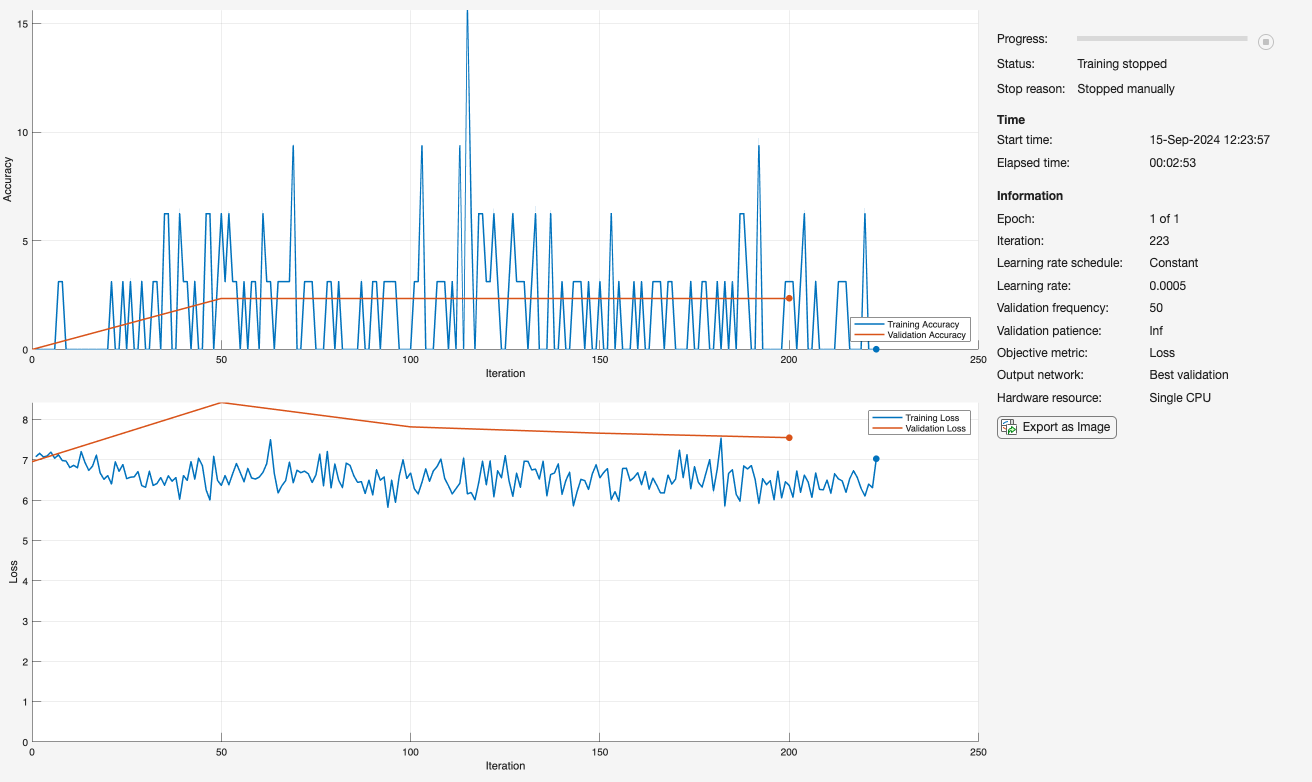

net = trainnet(trainData, trainLabels', layers,"crossentropy", options);

## Save network weights

save("/home/fogliodicarta/Desktop/InsectClassification/dna_matlab_weights.mat", "net");

val = 1×3234 single row vector
    0.0209    0.0188    0.0309    0.0210    0.0407    0.0283    0.0201    0.0206    0.0176    0.0303    0.0295    0.0361    0.0360    0.0228    0.0277    0.0262    0.0398    0.0407    0.0399    0.0378    0.0266    0.0230    0.0231    0.0196    0.0274    0.0390    0.0236    0.0217    0.0270    0.0190    0.0307    0.0221    0.0186    0.0198    0.0209    0.0189    0.0272    0.0272    0.0234    0.0225    0.0337    0.0207    0.0188    0.0233    0.0206    0.0215    0.0259    0.0256    0.0228    0.0233


argmax =          697         742         418         109        1039         418         109         418         742        1039         418        1039         418         109        1039         697        1039        1039        1039        1039         418         742         697         697         418         977         418         742         418         742         418         418         662         784         109         784         697         418         109         418         418         697         784         697         697         418        1039         418         418         418


argmax = 1×3234 categorical array
     697      742      418      109      1039      418      109      418      742      1039      418      1039      418      109      1039      697      1039      1039      1039      1039      418      742      697      697      418      977      418      742      418      742      418      418      662      784      109      784      697      418      109      418      418      697      784      697      697      418      1039      418      418      418      109      784      697      742      697      418      109      418      418      662      697      418      418      1039      1039      697      418      742      697      418      784      109      418      109      697      577      697      662      662      662      697      418      418      418      418      697      109      418      742      418      1039      697      784      109      418      697      418      697      697      784      109      418      784      697      418      784 

    0.0124



Error using dlnetwork/classify (line 850)
The classify function does not support dlnetwork objects. Use the predict function instead.